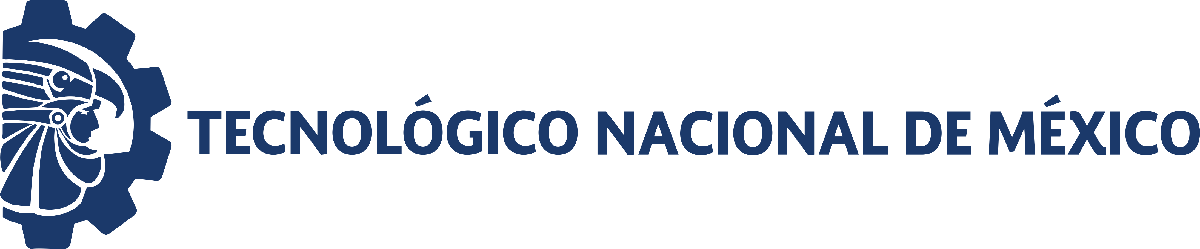                                 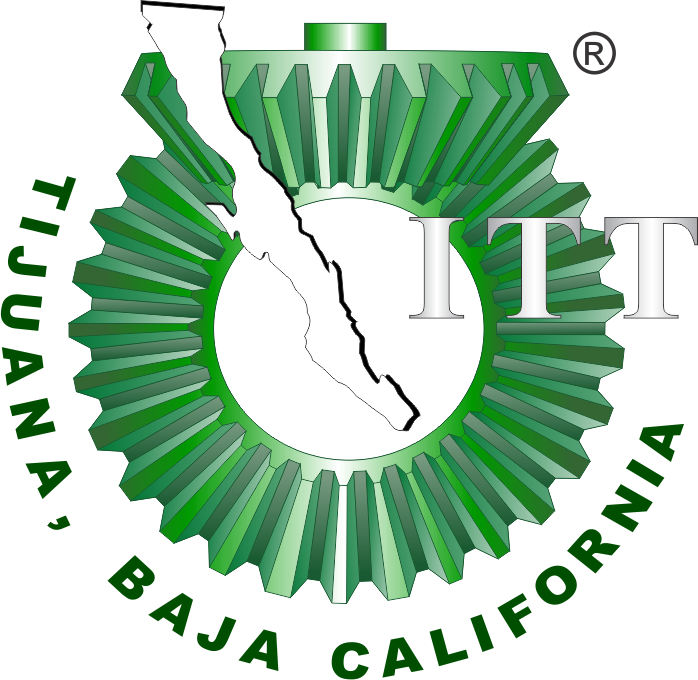

# Práctica 2: Sistema cardiovascular 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

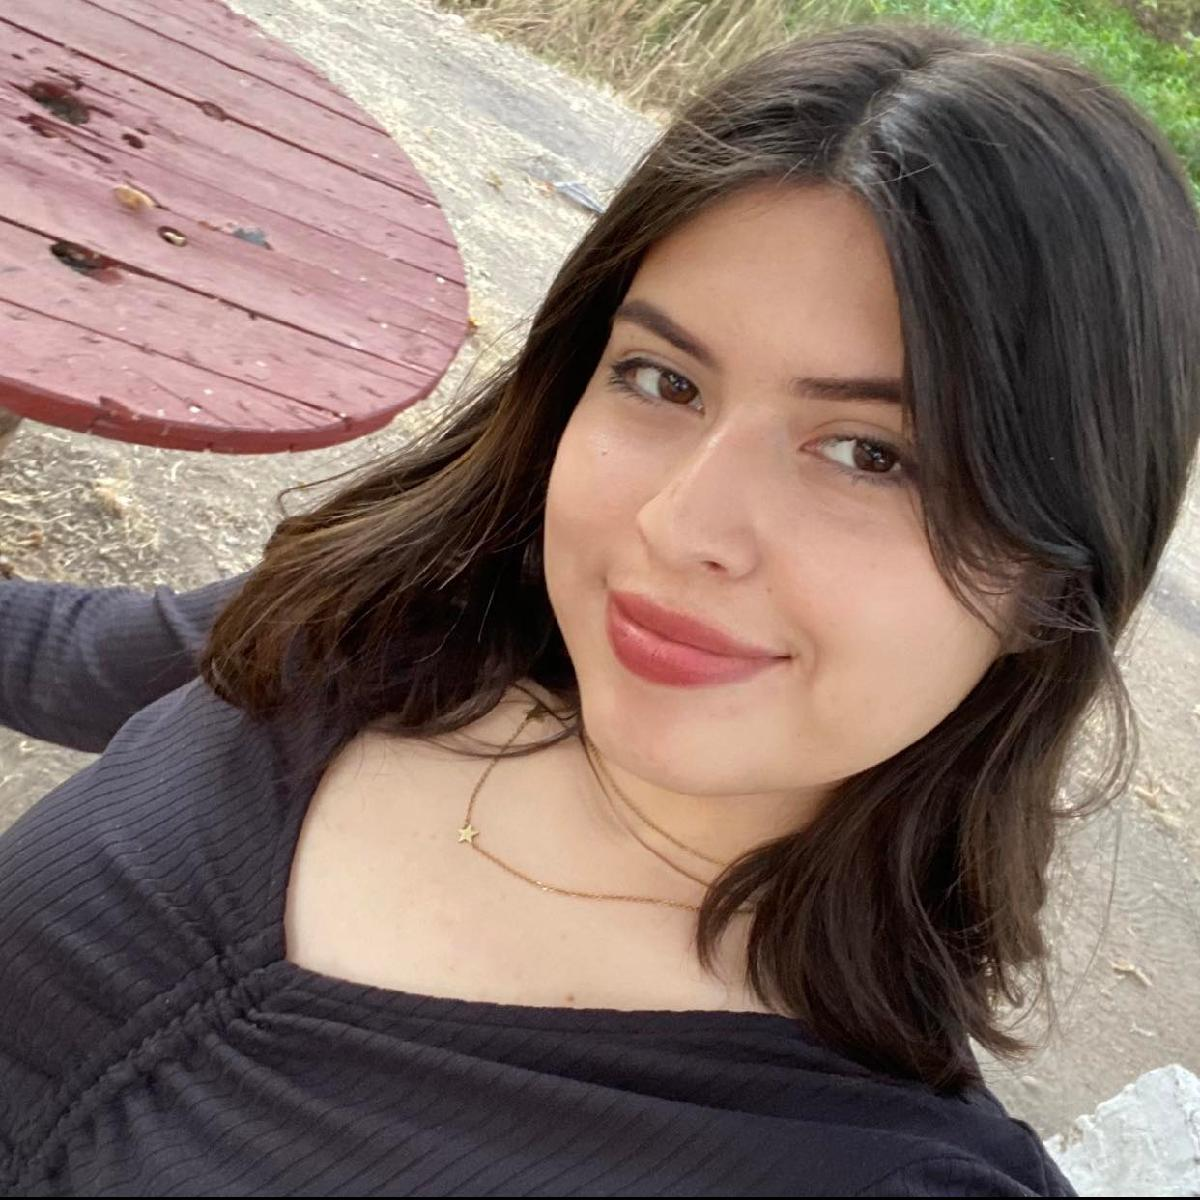

Nombre del alumno: **Lugo Valenzuela Liliana Fernanda**

Número de control: **21212165**

Correo institucional: **L21212165@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

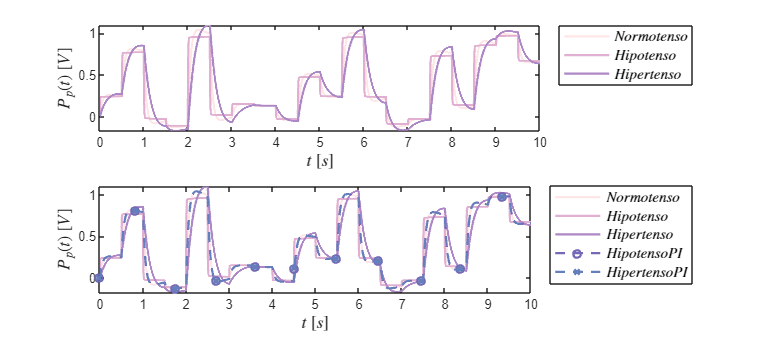

clc; clear; close all; warning('off','all')
tend='10';
file='SistemaP2';
open_system(file);
parameters.StopTime=tend;
parameters.Solver='ode23t';
parameters.MaxStep='1e-3';
set_param('SistemaP2/Ppa(t)','Minimum','-0.2');
set_param('SistemaP2/Ppa(t)','Maximum','1');
set_param('SistemaP2/Ppa(t)','Seed','106');
set_param('SistemaP2/Ppa(t)','SampleTime','0.5');
x= sim(file,parameters);
writematrix(x.Ppa,'Signal.xlsx')
plotsignals(x.t,x.Pp0,x.Pp1,x.Pp2,x.Pp3,x.Pp4)

## Respuesta en lazo abierto

## Hipotenso

Signal='Hipotenso';
open_system(file); 
x=sim(file,parameters);
opt=2;
s='Hipotenso';


## Hipertenso

Signal='Hipertenso';
open_system(file);
x=sim(file,parameters);
opt=3;
s='Hipertenso'; 

## Funcion: Respuesta a las senales

function plotsignals(t,Pp0,Pp1,Pp2,Pp3,Pp4, Signal)
   set(figure(), 'Color', 'w')
   set(gcf, 'units', 'centimeters', 'position', [1,1,18,8] )
   set(gca, 'FontName', 'Times New Roman', 'FontSize',11)
   hold on; grid off; box on;
   mycolors = [1.000, 0.902, 0.902;
               0.882, 0.686, 0.820;
               0.678, 0.533, 0.776;
               0.455, 0.412, 0.714;
               0.392, 0.498, 0.737;
               0.568, 0.678, 0.784;
               ];
   colororder(mycolors)



subplot(2,1,2)
   p=plot(t, Pp0, '-', t, Pp1, '-',t,Pp2, '-',t,Pp3,'--o',t,Pp4,'--X', ...
       'LineWidth', 1.5,'MarkerSize',5, 'MarkerIndices',1:1000:length(t));
 % set(p(5),'LineWidth',3);
   L = legend('$Normotenso$', '$Hipotenso$', '$Hipertenso$', '$HipotensoPI$','$HipertensoPI$');
   set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
   


   xlabel('$t$ $[s]$', 'Interpreter','Latex', 'FontSize',11)
   ylabel('$P_p(t)$ $[V]$', 'Interpreter','Latex', 'FontSize',11)

xlim([0,10]); xticks(0:1:10)
subplot(2,1,1)

   p1=plot(t, Pp0, '-', t, Pp1, '-',t,Pp2, '-', ...
       'LineWidth', 1.5,'MarkerSize',5, 'MarkerIndices',1:1000:length(t));
  %set(p1(3),'LineWidth',3);
   L = legend('$Normotenso$', '$Hipotenso$', '$Hipertenso$', '$HipotensoPI$','$HipertensoPI$');
   set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');



   xlabel('$t$ $[s]$', 'Interpreter','Latex', 'FontSize',11)
   ylabel('$P_p(t)$ $[V]$', 'Interpreter','Latex', 'FontSize',11)

xlim([0,10]); xticks(0:1:10);

exportgraphics(gcf,['CV.pdf'],'ContentType','vector')
exportgraphics(gcf,['CV.png'],'ContentType','vector')
end
